# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

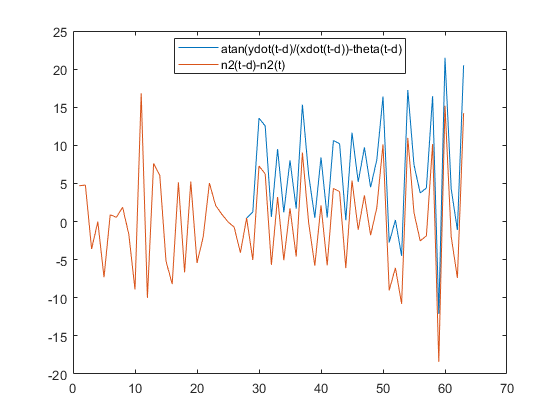

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k;

down_sample_amount = 5;

% Circle
D = .8; k = 20; h = 0.02;
position = importdata("position_Array.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
statea(:,1) =[position(1,1); position(2,1); 0];

state(:,1) =[position(1,1); position(2,1); 0];

xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1);  

xba(1) = state(1,1) + D*cos(state(3,1));
yba(1) = state(2,1) + D*sin(state(3,1));
thetaa(1) = state(3,1); 


  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;
  
  xVelocitya = (position(1,t+1) - position(1,t))/h;
  yVelocitya = (position(2,t+1) - position(2,t))/h;
  n2(1) = 0;
for t =1 : T
    n1 = 5*randn(1);
    n2 = 5*randn(1);
    noise2(t+1) = n2;
    % x= current state
    xa= [xba(t); yba(t); thetaa(t)];
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [va, wa] = controller(xa, xVelocitya(t), yVelocitya(t),position(:,t));
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    % use the dynamics with desired velocities to generate the velocities
    dot_xa = dynamics(xa,va,w,n1,n2);
    dot_x = dynamics(x,v,w,n1,n2);
     linear_vela(t) = va+n1;
     angular_vela(t) = wa+n2;
     
     linear_vel(t) = v+n1;
     angular_vel(t) = w+n2;
    % centroid dynamics
    %actual
    statea(:,t+1) = statea(:,t) + h* [(va+n1)*cos(statea(3,t)); (va+n1)*sin(statea(3,t)); wa+n2];  
    %noise
    state(:,t+1) = state(:,t) + h* [(v+n1)*cos(state(3,t)); (v+n1)*sin(state(3,t)); w+n2];
    
   

    % integrate the position to get the new position
    
    %actual
    xba(t+1) = xba(t) + dot_xa(1)*h;
    yba(t+1) = yba(t) + dot_xa(2)*h;
    thetaa(t+1) = thetaa(t) + dot_xa(3)*h;
    
    %estimated
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = atan2((state(2,t+1)-state(2,t))/(v+n1),(state(1,t+1)-state(1,t))/(v+n1)) + dot_x(3)*h;
    int_noise(t) = noise2(t+1)-noise2(t);
    
    e(t) = thetaa(t) - theta(t)-int_noise(t);
end
figure
plot(e)
hold on
plot(-int_noise)
legend('atan(ydot(t-d)/(xdot(t-d))-theta(t-d)','n2(t-d)-n2(t)','Location',"best")

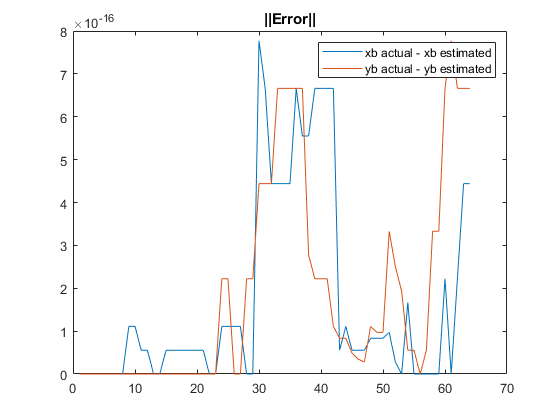

% save("noise_centroid.mat","state")
error = abs([xba-xb; yba-yb]);
figure

plot(error(1,:))
hold on
plot(error(2,:))
legend('xb actual - xb estimated', 'yb actual - yb estimated')
title('||Error||')
hold off

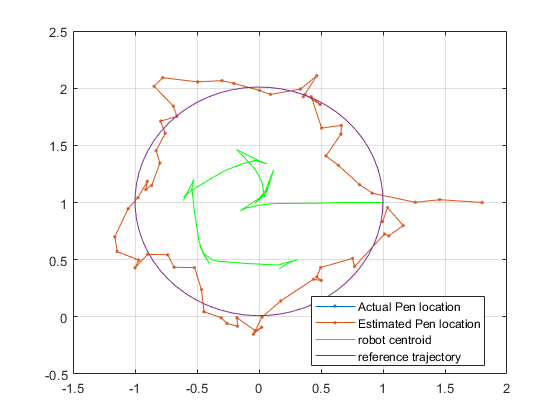


figure
plot(xba, yba, '.-')

hold on;
plot(xb, yb, '.-')
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
grid on;
legend('Actual Pen location','Estimated Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

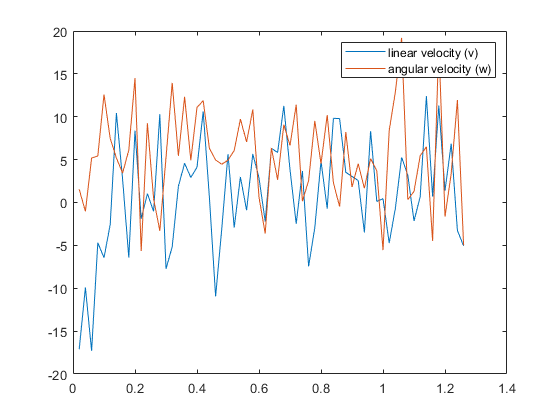


figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end